## 评估功能连接分析的可靠性

- 生成2个细胞的模拟数据

- 控制spike的密集程度

- 控制同步发放的程度。

## Main

核心参数 para_spikeRatio，para_spikeRatio较大时（>0.1），误差较大

真实情况下细胞发放的ratio是较低的，一般<0.01/0.05? 这里可以统计看看

clc
clear
% close all


参数设置

% *************************
para_Len = 1000;          % 序列长度
para_spikeRatio = 0.01;   % 发放时间比例
para_synchRatio = 0.05:0.05:0.8;   % 同步发放的比例
para_repeatNum = 10;    % 实验整体重复次数
para_randNum = 100;      % 计算random cospike 随机次数
% *************************

测试

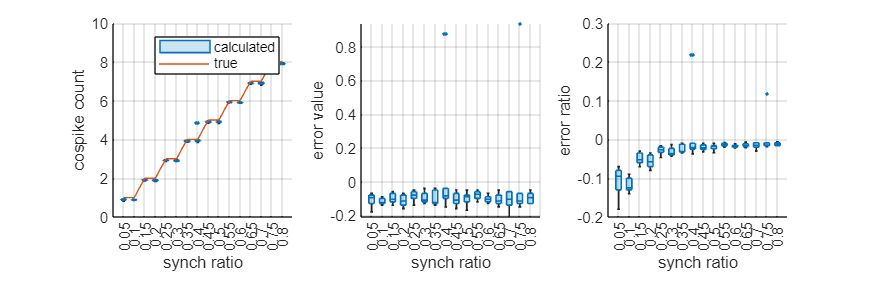

cospike_true = round(para_Len*para_spikeRatio*para_synchRatio);
cospike_cal = zeros(para_repeatNum,length(para_synchRatio));

for si = 1:length(para_synchRatio)
    for ri = 1:para_repeatNum
        % 根据条件，生成 spike1 spike2
        indrand = randperm(para_Len);
        indCospike = indrand(1:cospike_true(si));
        indOther = indrand(cospike_true(si)+1:end);
        num_nonCospike = para_Len*para_spikeRatio - cospike_true(si);
        indOnly1 = indOther(1:num_nonCospike);
        indOther = indOther(randperm(length(indOther)));
        indOnly2 = indOther(1:num_nonCospike);
        spike1 = zeros(para_Len,1);
        spike1([indCospike indOnly1]) = 1;
        spike2 = zeros(para_Len,1);
        spike2([indCospike indOnly2]) = 1;
        % cospike analysis
        conn_true = sum(spike1+spike2==2);
        conn_rand = zeros(para_randNum,1);
        for rand_i = 1:para_randNum
            spike1_rand = spike1(randperm(length(spike1)));
            spike2_rand = spike1(randperm(length(spike2)));
            conn_rand(rand_i,1) = sum(spike1_rand+spike2_rand==2);
        end
        cospike_cal(ri,si) = conn_true-mean(conn_rand);
    end
end

%  visualization
figure
tiledlayout(1,3)
nexttile; hold on; grid on
b=boxchart(cospike_cal);
b.JitterOutliers = 'on'; b.MarkerStyle = '.';
plot(cospike_true)
set(gca,'XTickLabel',para_synchRatio)
xlabel('synch ratio'); ylabel('cospike count')
legend('calculated','true')
% calculate error
errValue = cospike_cal-repmat(cospike_true,para_repeatNum,1);
errRatio = errValue./repmat(cospike_true,para_repeatNum,1);
nexttile; hold on; grid on
b=boxchart(errValue);
b.JitterOutliers = 'on'; b.MarkerStyle = '.';
set(gca,'XTickLabel',para_synchRatio)
xlabel('synch ratio'); ylabel('error value')
nexttile; hold on; grid on
b=boxchart(errRatio);
b.JitterOutliers = 'on'; b.MarkerStyle = '.';
set(gca,'XTickLabel',para_synchRatio)
xlabel('synch ratio'); ylabel('error ratio')

set(gcf,'Position',[100 100 750 250])

## 控制 firingrate

2024-02-08

clc
clear

clc
clear
% close all


参数设置

% *************************
para_Len = 1000;          % 序列长度
para_spikeRatio = 0.001:0.002:0.05;   % 发放时间比例
para_repeatNum = 10;    % 实验整体重复次数
para_randNum = 100;      % 计算random cospike 随机次数
% *************************

测试

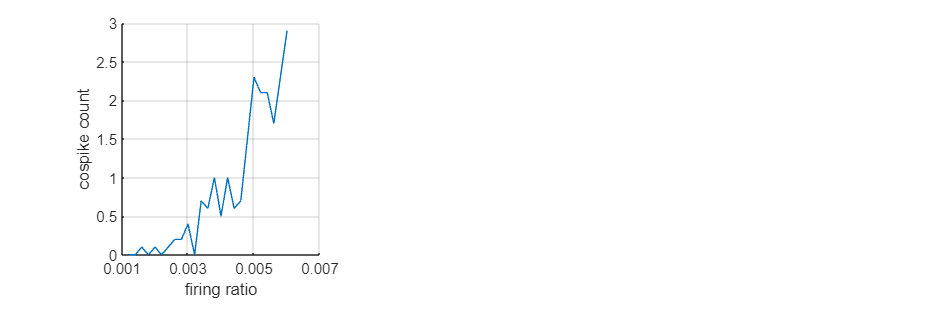

cospike_cal = zeros(para_repeatNum,length(para_spikeRatio));
for si = 1:length(para_spikeRatio)
    cospike_true = round(para_Len*para_spikeRatio(si));
    for ri = 1:para_repeatNum
        % 根据条件，生成 spike1 spike2
        spike1 = zeros(para_Len,1);
        spike1(randperm(para_Len,cospike_true)) = 1;
        spike2 = zeros(para_Len,1);
        spike2(randperm(para_Len,cospike_true)) = 1;
        cospike_cal(ri,si) = sum(spike1+spike2==2);
        % % random analysis
        % conn_rand = zeros(para_randNum,1);
        % for rand_i = 1:para_randNum
        %     spike1_rand = spike1(randperm(length(spike1)));
        %     spike2_rand = spike1(randperm(length(spike2)));
        %     conn_rand(rand_i,1) = sum(spike1_rand+spike2_rand==2);
        % end
        % cospike_rnd(ri,si) = conn_true-mean(conn_rand);
    end
end

%  visualization
figure
tiledlayout(1,3)
nexttile; hold on; grid on
b=plot(mean(cospike_cal,1));
% b.JitterOutliers = 'on'; b.MarkerStyle = '.';
% legend('calculated','true')
set(gca,'XTickLabel',para_spikeRatio)
xlabel('firing ratio'); ylabel('cospike count')
% % calculate error
% errValue = cospike_cal-repmat(cospike_true,para_repeatNum,1);
% errRatio = errValue./repmat(cospike_true,para_repeatNum,1);
% nexttile; hold on; grid on
% b=boxchart(errValue);
% b.JitterOutliers = 'on'; b.MarkerStyle = '.';
% set(gca,'XTickLabel',para_synchRatio)
% xlabel('synch ratio'); ylabel('error value')
% nexttile; hold on; grid on
% b=boxchart(errRatio);
% b.JitterOutliers = 'on'; b.MarkerStyle = '.';
% set(gca,'XTickLabel',para_synchRatio)
% xlabel('synch ratio'); ylabel('error ratio')

set(gcf,'Position',[100 100 750 250])